close all; clear; clc;

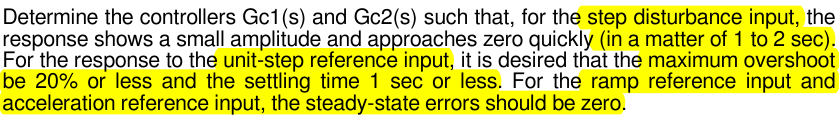

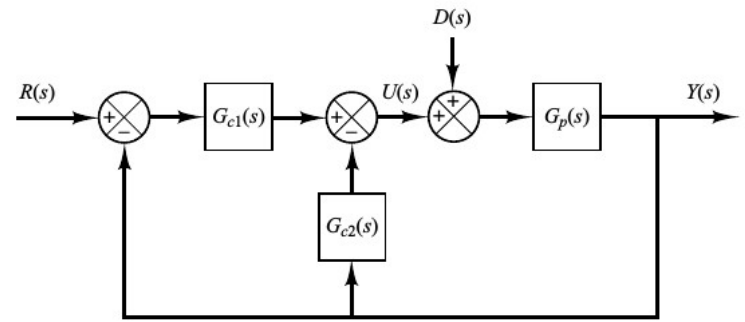

## Función de transferencia de la planta

syms s
K  = 2;
A  = [1 1];
B  = conv([1 0],conv([1 3],[1 5]));
Gp = tf(K*A,B)

Gp =
 
       2 s + 2
  ------------------
  s^3 + 8 s^2 + 15 s
 
Continuous-time transfer function.



Gp_sym = poly2sym(K*A, s)/poly2sym(B, s)

$$Gp\_sym = \frac{2\,s+2}{s^{3}+8\,s^{2}+15\,s}$$

## Polos/ceros de la planta

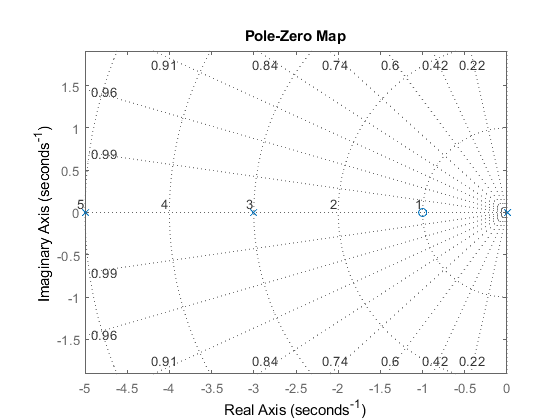

pzmap(Gp); grid on; axis('equal')

Bien, hay que notar que el sistema a lazo abierto tiene un polo en el origen, por lo tanto tiene un integrador puro a la salida.

Por ejemplo podría ser debido a que es una salida de posición obtenida por integración de la velocidad.

# Análisis de las funciones de transferencia

## Función de transferencia del controlador auxiliar

syms kp kd ki tau_z
Gc_sym = collect((kp + ki/s + kd*s)*(tau_z*s + 1)/poly2sym(A, s), s) % Con el filtro y un cero del controlador % Con el filtro de los ceros como la teoría

$$Gc\_sym = \frac{\left(\mathrm{kd}\,\tau_{z}\right)\,s^{3}+\left(\mathrm{kd}+\mathrm{kp}\,\tau_{z}\right)\,s^{2}+\left(\mathrm{kp}+\mathrm{ki}\,\tau_{z}\right)\,s+\mathrm{ki}}{s^{2}+s}$$

## Función de transferencia a lazo cerrado desde la perturbación

Gd_sym = collect(Gp_sym/(1 + Gp_sym*Gc_sym), s)

$$Gd\_sym = \frac{2\,s^{2}+2\,s}{s^{4}+\left(2\,\mathrm{kd}\,\tau_{z}+8\right)\,s^{3}+\left(2\,\mathrm{kd}+2\,\mathrm{kp}\,\tau_{z}+15\right)\,s^{2}+\left(2\,\mathrm{kp}+2\,\mathrm{ki}\,\tau_{z}\right)\,s+2\,\mathrm{ki}}$$

## Función de transferencia a lazo cerrado desde la referencia

syms Gc1_sym
Gr_sym = collect(Gc1_sym*Gp_sym/(1 + Gp_sym*Gc_sym), s)

$$Gr\_sym = \frac{\left(2\,{\mathrm{Gc}}_{1,\mathrm{sym}}\right)\,s^{2}+\left(2\,{\mathrm{Gc}}_{1,\mathrm{sym}}\right)\,s}{s^{4}+\left(2\,\mathrm{kd}\,\tau_{z}+8\right)\,s^{3}+\left(2\,\mathrm{kd}+2\,\mathrm{kp}\,\tau_{z}+15\right)\,s^{2}+\left(2\,\mathrm{kp}+2\,\mathrm{ki}\,\tau_{z}\right)\,s+2\,\mathrm{ki}}$$

## Función de transferencia de C1

[num, den] = numden(Gr_sym);
w          = coeffs(den, s, 'All');
w          = sum(w(end-2:end).*s.^[2 1 0]);
num        = simplify(num/Gc1_sym);
Gc1_sym    = w/num

$$Gc1\_sym = \frac{\left(2\,\mathrm{kd}+2\,\mathrm{kp}\,\tau_{z}+15\right)\,s^{2}+\left(2\,\mathrm{kp}+2\,\mathrm{ki}\,\tau_{z}\right)\,s+2\,\mathrm{ki}}{2\,s\,\left(s+1\right)}$$

## Función de transferencia de C2

Gc2_sym = collect(Gc_sym - Gc1_sym, s)

$$Gc2\_sym = \frac{\left(2\,\mathrm{kd}\,\tau_{z}\right)\,s^{2}-15\,s}{2\,s+2}$$

## Función de transferencia a LC respecto a la ref. final

Gr_sym = collect(subs(Gr_sym), s)

$$Gr\_sym = \frac{\left(2\,\mathrm{kd}+2\,\mathrm{kp}\,\tau_{z}+15\right)\,s^{2}+\left(2\,\mathrm{kp}+2\,\mathrm{ki}\,\tau_{z}\right)\,s+2\,\mathrm{ki}}{s^{4}+\left(2\,\mathrm{kd}\,\tau_{z}+8\right)\,s^{3}+\left(2\,\mathrm{kd}+2\,\mathrm{kp}\,\tau_{z}+15\right)\,s^{2}+\left(2\,\mathrm{kp}+2\,\mathrm{ki}\,\tau_{z}\right)\,s+2\,\mathrm{ki}}$$

# Asignación de polos

## Polinomio característico a LC

[num, den]  = numden(Gr_sym);
numGr       = collect(num, s)

$$numGr = \left(2\,\mathrm{kd}+2\,\mathrm{kp}\,\tau_{z}+15\right)\,s^{2}+\left(2\,\mathrm{kp}+2\,\mathrm{ki}\,\tau_{z}\right)\,s+2\,\mathrm{ki}$$

denGr       = collect(den, s)

$$denGr = s^{4}+\left(2\,\mathrm{kd}\,\tau_{z}+8\right)\,s^{3}+\left(2\,\mathrm{kd}+2\,\mathrm{kp}\,\tau_{z}+15\right)\,s^{2}+\left(2\,\mathrm{kp}+2\,\mathrm{ki}\,\tau_{z}\right)\,s+2\,\mathrm{ki}$$

[num, den] = numden(Gd_sym);
numD = collect(num, s)

$$numD = 2\,s^{2}+2\,s$$

denD = collect(den, s)

$$denD = s^{4}+\left(2\,\mathrm{kd}\,\tau_{z}+8\right)\,s^{3}+\left(2\,\mathrm{kd}+2\,\mathrm{kp}\,\tau_{z}+15\right)\,s^{2}+\left(2\,\mathrm{kp}+2\,\mathrm{ki}\,\tau_{z}\right)\,s+2\,\mathrm{ki}$$

## Polinomio objetivo a LC

syms w1 w2 z1 z2
obj_sym = collect((s^2 + 2*z1*w1*s + w1^2)*(s^2 + 2*z2*w2*s + w2^2), s);
disp('OBJETIVO');

OBJETIVO


disp(obj_sym);

$$s^{4}+\left(2\,w_{1}\,z_{1}+2\,w_{2}\,z_{2}\right)\,s^{3}+\left({w_{1}}^{2}+4\,z_{1}\,z_{2}\,w_{1}\,w_{2}+{w_{2}}^{2}\right)\,s^{2}+\left(2\,z_{2}\,{w_{1}}^{2}\,w_{2}+2\,z_{1}\,w_{1}\,{w_{2}}^{2}\right)\,s+{w_{1}}^{2}\,{w_{2}}^{2}$$

obj             = subs(obj_sym);
denGrCoeffs     = coeffs(denGr, s, 'All');
objCoeffs       = coeffs(obj, s, 'All')

$$objCoeffs = \left(\begin{array}{ccccc} 1 & 2\,w_{1}\,z_{1}+2\,w_{2}\,z_{2} & {w_{1}}^{2}+4\,z_{1}\,z_{2}\,w_{1}\,w_{2}+{w_{2}}^{2} & 2\,z_{2}\,{w_{1}}^{2}\,w_{2}+2\,z_{1}\,w_{1}\,{w_{2}}^{2} & {w_{1}}^{2}\,{w_{2}}^{2} \end{array}\right)$$

eqs             = denGrCoeffs(2:end)==objCoeffs(2:end)

$$eqs = \left(\begin{array}{cccc} 2\,\mathrm{kd}\,\tau_{z}+8=2\,w_{1}\,z_{1}+2\,w_{2}\,z_{2} & 2\,\mathrm{kd}+2\,\mathrm{kp}\,\tau_{z}+15={w_{1}}^{2}+4\,z_{1}\,z_{2}\,w_{1}\,w_{2}+{w_{2}}^{2} & 2\,\mathrm{kp}+2\,\mathrm{ki}\,\tau_{z}=2\,z_{2}\,{w_{1}}^{2}\,w_{2}+2\,z_{1}\,w_{1}\,{w_{2}}^{2} & 2\,\mathrm{ki}={w_{1}}^{2}\,{w_{2}}^{2} \end{array}\right)$$

Ts          = linspace(0.2, 4, 20); % Time Settling
z1_mean     = 0.70;
w1_mean     = 4./(Ts*z1_mean);

w1_vec      = w1_mean;
z1_vec      = [z1_mean];
z2_vec      = [z1_mean];

n           = 1;
indices     = zeros(1, 4);
ganancias   = zeros(1, 4);
soluciones  = zeros(1, 4);
c           = 1;
for i = 1:length(w1_vec)
    w1      = w1_vec(i);
    w2_vec  = [11.5966225*w1];
    for j = 1:length(w2_vec)
        w2       = w2_vec(j);
        for k = 1:length(z1_vec)
            z1 = z1_vec(k);
            for l = 1:length(z2_vec)
                z2 = z2_vec(l);
                eqs_aux     = subs(eqs);
                sol         = solve(eqs_aux, [kp kd ki tau_z], 'ReturnConditions', true);
                gains       = [double(sol.kp(1)) double(sol.kd(1)) double(sol.ki(1)) double(sol.tau_z(1))];
                num         = sym2poly(subs(numGr, [kp, kd, ki, tau_z], gains));
                den         = sym2poly(subs(denGr, [kp, kd, ki, tau_z], gains));
                G           = tf(num, den);
                aux         = stepinfo(G);
                
                num         = sym2poly(numD);
                den         = sym2poly(subs(denD, [kp, kd, ki, tau_z], gains));
                G           = tf(num, den);
                aux1         = stepinfo(G);
                
                indices(c,:)    = [i, j, k, l];
                ganancias(c, :) = gains;
                if ((aux.Overshoot < 20) && (aux.SettlingTime < 1))
                    if (aux1.SettlingTime < 2)
                        soluciones(n, 1:4) = gains;
                        n               = n + 1;
                        disp('Si');
                    end
                end
                c = c + 1;
            end
        end
    end
end

Si
Si
Si
Si
Si
Si
Si
Si
Si
Si


length(soluciones)

ans = 20

length(ganancias)

ans = 20

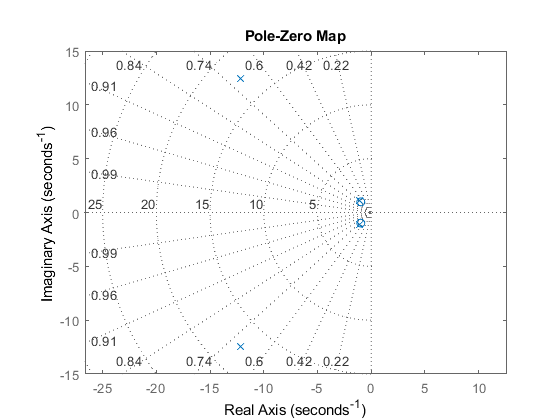

n =19;
num               = sym2poly(subs(numGr, [kp, kd, ki, tau_z], ganancias(n,:)));
den               = sym2poly(subs(denGr, [kp, kd, ki, tau_z], ganancias(n,:)));
G                 = tf(num, den);
pzmap(G); grid on; axis('equal')

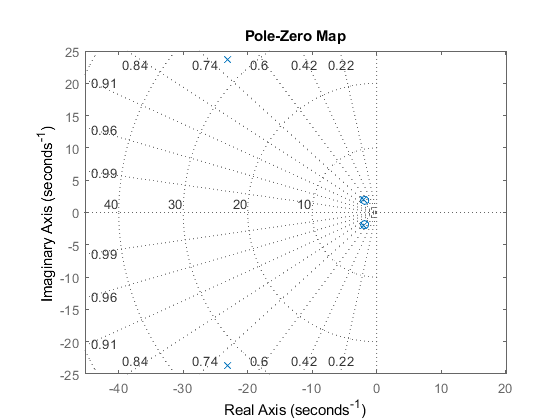

n =10;
num               = sym2poly(subs(numGr, [kp, kd, ki, tau_z], soluciones(n,:)));
den               = sym2poly(subs(denGr, [kp, kd, ki, tau_z], soluciones(n,:)));
G                 = tf(num, den);
pzmap(G); grid on; axis('equal')

soluciones(n,1:3)

ans = 	1.0e+03 *

    2.2134    0.5535    4.4809


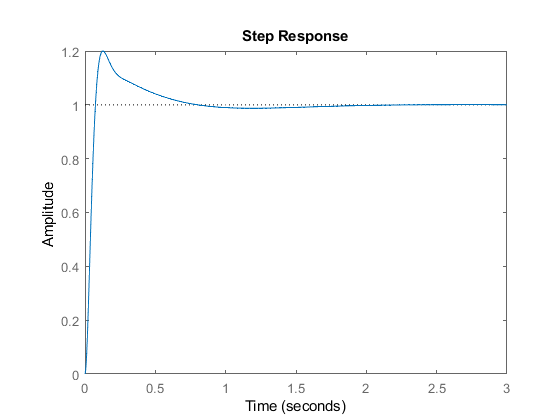

step(G)

num               = sym2poly(numD);
den               = sym2poly(subs(denD, [kp, kd, ki, tau_z], soluciones(n,:)));
Gd                = tf(num, den);
stepinfo(Gd)

ans = struct with fields:
        RiseTime: 0
    SettlingTime: 1.8405
     SettlingMin: -2.2285e-04
     SettlingMax: 0.0015
       Overshoot: Inf
      Undershoot: Inf
            Peak: 0.0015
        PeakTime: 0.1032


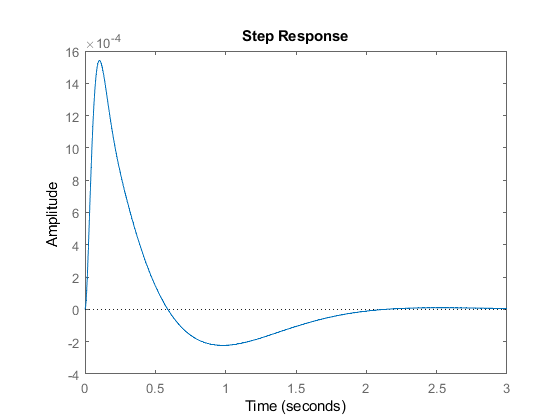

step(Gd)

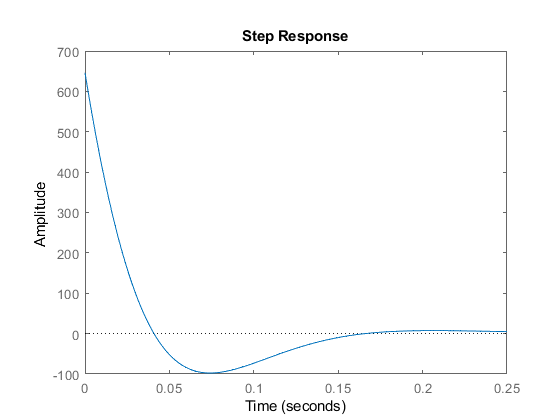

Gru = G/Gp;
Gdu = Gd/Gp;
step(Gru)

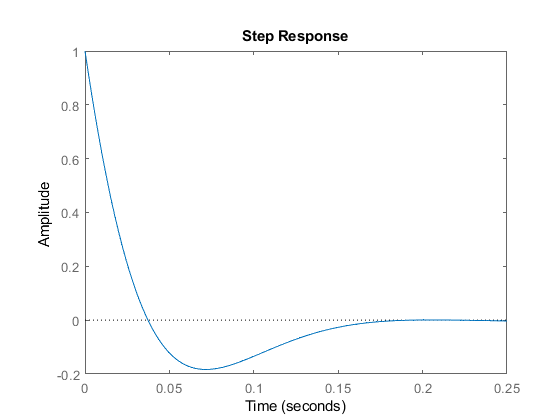

step(Gdu)